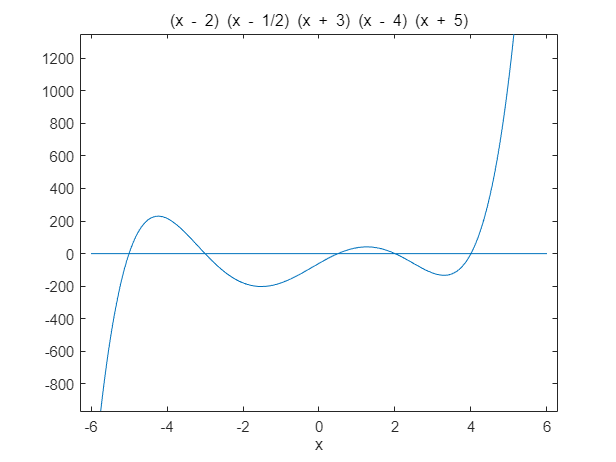

clc;
clear all;
close all;

syms x;
y1 = (x+5)*(x-4)*(x+3)*(x-2)*(x-1/2);%第一个非线性方程
y2 = (x+5)*(x-4)^2*(x+3)*(x+5/2);%第二个非线性方程
ezplot(y1);
hold on
line([-6,6],[0,0]);%将画出（-6,0）到(6,0)的一条直线
hold off

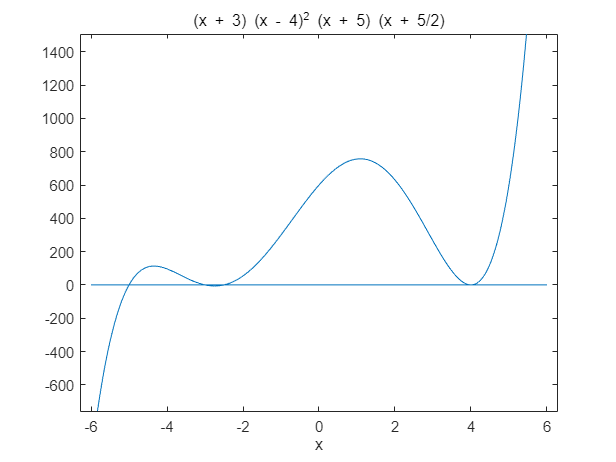

ezplot(y2)
hold on
line([-6,6],[0,0]);%将画出（-6,0）到(6,0)的一条直线

%先初步判断零点的分布
%发现有四个零点，我们不妨将整个区间[-6,6]平分成4
x0 = zeros(1,5);
y1 = @f_1; 
y2 = @f_2;
y = y2;

k = 0;
L = 1/2;
 for i = -6:L:6  
    if(y(i)*y(i+L)<=0)
        k = k + 1;
        x0(k) = f_Bis(y,i,i+L,0.001);
    end
 end
fprintf("零点的横坐标为:")

零点的横坐标为:

x0 = unique(x0);
B(y,x0)

$$dy = \left(x+3\right)\,{\left(x-4\right)}^{2}\,\left(x+5\right)+\left(x+3\right)\,{\left(x-4\right)}^{2}\,\left(x+\frac{5}{2}\right)+{\left(x-4\right)}^{2}\,\left(x+5\right)\,\left(x+\frac{5}{2}\right)+\left(2\,x-8\right)\,\left(x+3\right)\,\left(x+5\right)\,\left(x+\frac{5}{2}\right)$$

函数的一阶导数值:

$$dy\_x = \left(\begin{array}{cccc} 405 & -49 & \frac{845}{16} & 0 \end{array}\right)$$

函数的二阶导数值:

$$ddy\_x = \left(\begin{array}{cccc} -909 & 175 & 221 & 819 \end{array}\right)$$

ans =    -5.0000   -3.0000   -2.5000    4.0000
    1.0000    1.0000    1.0000    2.0000


% function y1 = f_1(x)
%     y1 = (x+5)*(x-4)*(x+3)*(x-2)*(x-1/2)
% end

% function y2 = f_2(x)
%     y2 = (x+5)*(x-4)^2*(x+3)*(x+5/2);
% end